L1=0.29; L2=0.36;
Px = [];
Py = [];

i=1;
for t1 = 0:pi/30:2*pi
    j=1;
    for t2 = 0:pi/30:2*pi
        Px(i,j) = L1*sin(t1)+L2*sin(t2);
        Py(i,j) = L1*cos(t1)+L2*cos(t2);
        j = j+1;
    end
    i = i+1;
end


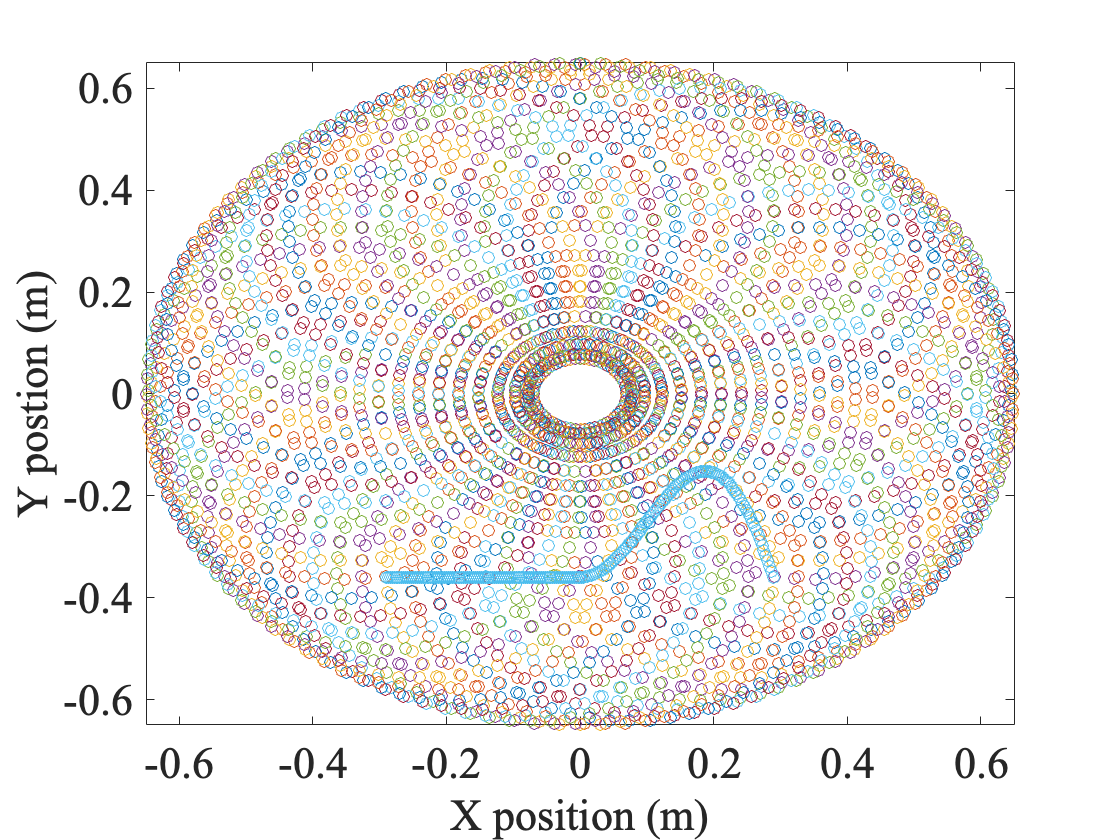

plot(Px,Py,'o')
hold on
plot(point_Px,point_Py,'o')
hold off
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',22)
xticklabels("auto")
xlabel('X position (m)',"FontSize",22)
ylabel('Y postion (m)',"FontSize",22)
%print('-dpng','ROM.jpg','-r1200')